fs=48000;
f1 = 17e3;   
f2 = 18e3;
chirp_len=960;
mode='s7/';
% 读取文件
fileFolder = fullfile(['receive/', mode]);
dirOutput = dir(fullfile(fileFolder,'*.pcm'));
fileNames = {dirOutput.name};
file_name = fileNames{end}

file_name = '20220326110638.pcm'

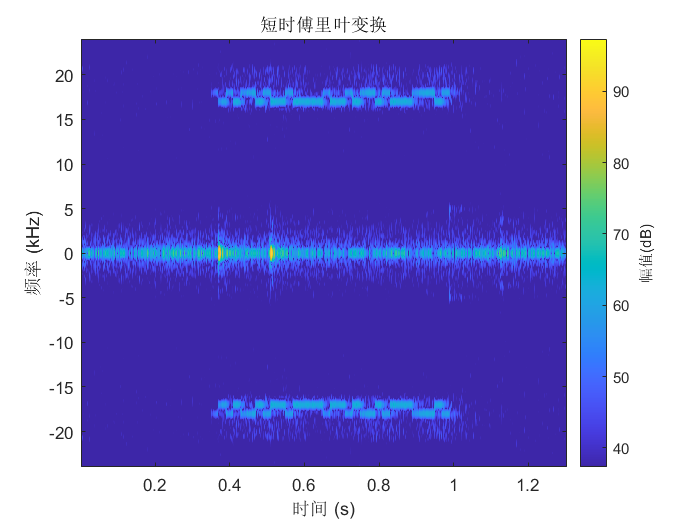

file=['receive/' , mode, file_name];
data= importdata(file);

data=data(15000:end-50000);

stft(data, fs, "FFTLength", 1024)


time = length(data);
t = 0:1/fs:(time-1)/fs;

% 获得超声波部分
data=highpass(data, 15000, fs);
% stft(data, fs, "FFTLength", 1024)

% 获得有效数据
A = movmean(abs(data), 20);
thresh = (max(A) - min(A))/7 + min(A);
inds = find(A > thresh);  % 找信号高于thre的下标位置
valid_data = data(inds(1):inds(end));  % 截取信号
if(length(valid_data)<32*chirp_len)
    valid_data=padarray(valid_data,32*chirp_len-length(valid_data), "pre");
else
    valid_data=valid_data(1:32*chirp_len);
end
% 
% stft(valid_data, fs, "FFTLength", 1024)

% 解调01信号
res=[];
for i= 1:chirp_len:length(valid_data)
    temp=valid_data(i:i+chirp_len-1);
    [argv, argmin]=max(abs(fft(temp, fs)));
    if(abs(argmin-f1)<abs(argmin-f2))
        res= [res 0];
    else
        res=[res 1];
    end
end
% 转换为ip
res;
str_res= sprintf('%1d', res)

str_res = '10101101001000010010110100011101'

deci_res=bin2dec(str_res)

deci_res = 2.9046e+09

IPVector= deci_res;
test=strcat(num2str(bitand(bitshift(IPVector,-24), 255)),'.',num2str(bitand(bitshift(IPVector,-16), 255)) ,'.',num2str(bitand(bitshift(IPVector,-8), 255)) ,'.',num2str(bitand(bitshift(IPVector,0), 255))  )

test = '173.33.45.29'